clear all; close all; clc;
global l1 l2 L H r13 r23 r33
l1 = 0; l2 = 0; L = 0.1; H = 0.2; r13 = 0; r23 = 0; r33 = 0; 

% Points A and B - ALSO HARDCODED IN FUNCTIONS
pa = [0.4 0 0.8]; pb = [0.25 -0.5 1];

% Limitations on Joint variables
theta1_limits = [-pi; pi];
theta2_limits = [-pi/2; pi/2];
d3_min = 0;

% Define time vector
dt = 0.01; t_0 = 0; t_f = 2;
t = t_0:dt:t_f;

% % Check that a straight line can work
% % direction = (pb - pa)./norm((pb - pa));
% step_size = (pb - pa)./length(t);
% Waypoints = zeros(length(t), 3);
% for i=0:length(t)-1
%     Waypoints(i+1, :) = pa + i * step_size;
% end

% % Check the IK for all Waypoints
% elbows = ones(length(t),1);
% Qs = inverse_kins(Waypoints, elbows);
% Ps = forward_kins(Qs);
% norm(Ps - Waypoints) % This value is close to zero, and FK approved the joint values within limits.

## Constant Linear Velocity Profile

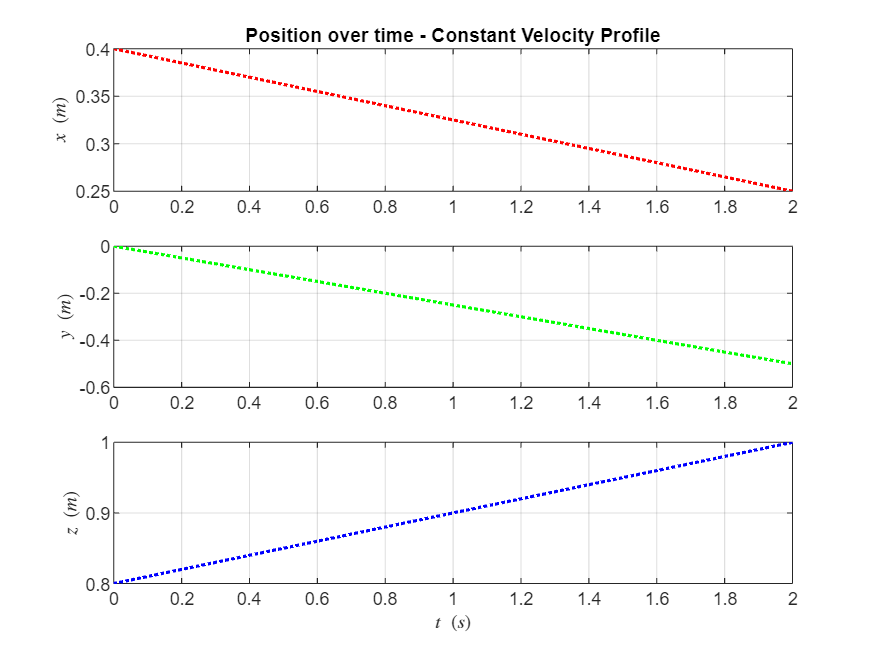

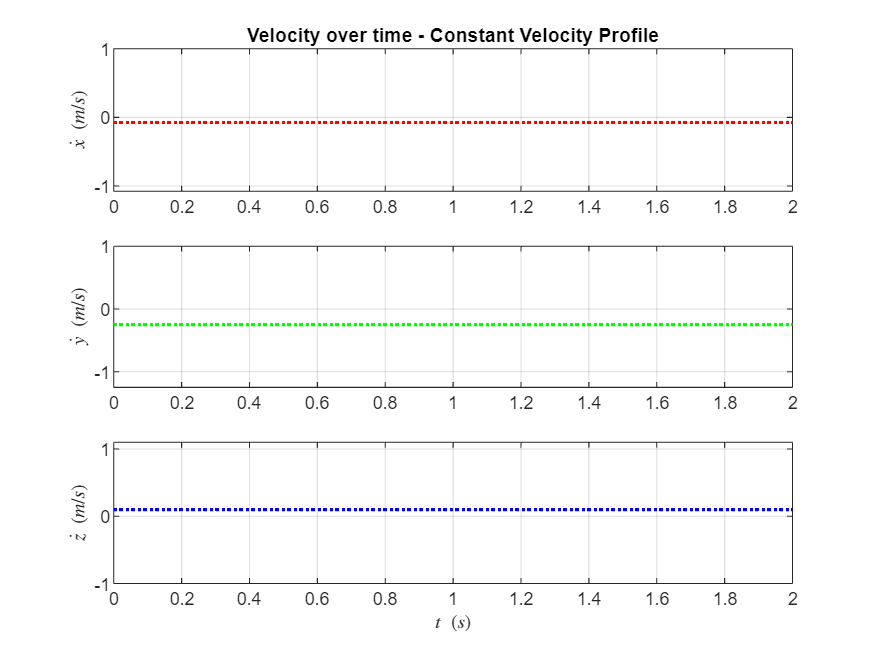

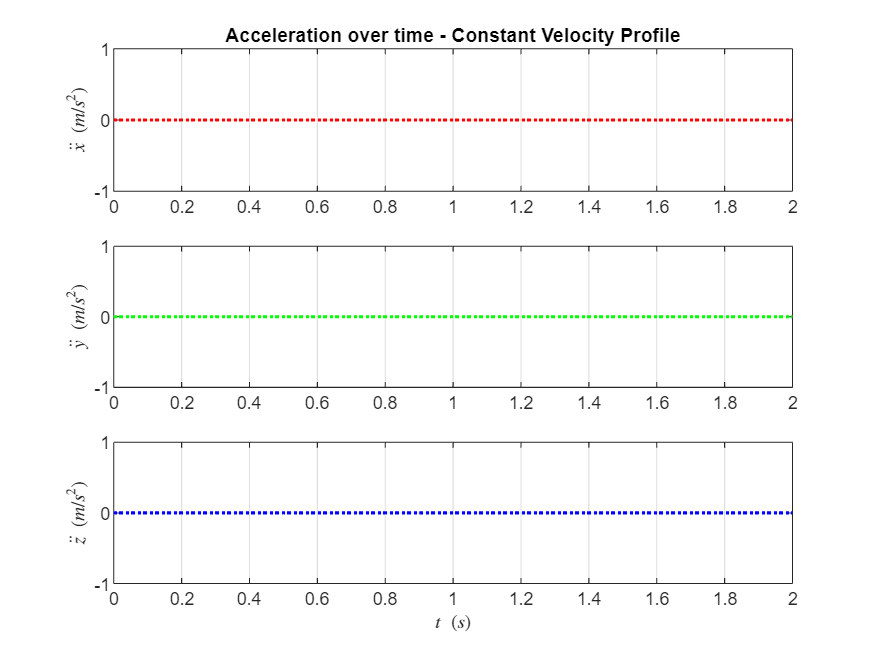

% Compute positions velocities and accelerations.
X = x_plan("Constant", t); 
V = v_plan("Constant", t); 
A = a_plan("Constant", t);
Task_traj_plotter("Constant", X, V, A, t) % some custom function to plot everything neatly in Task Space

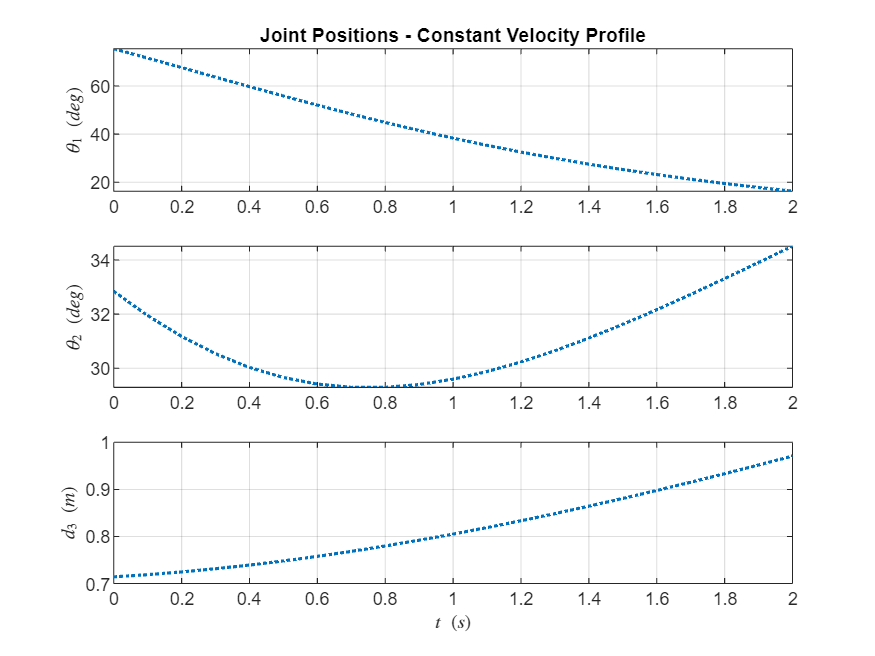

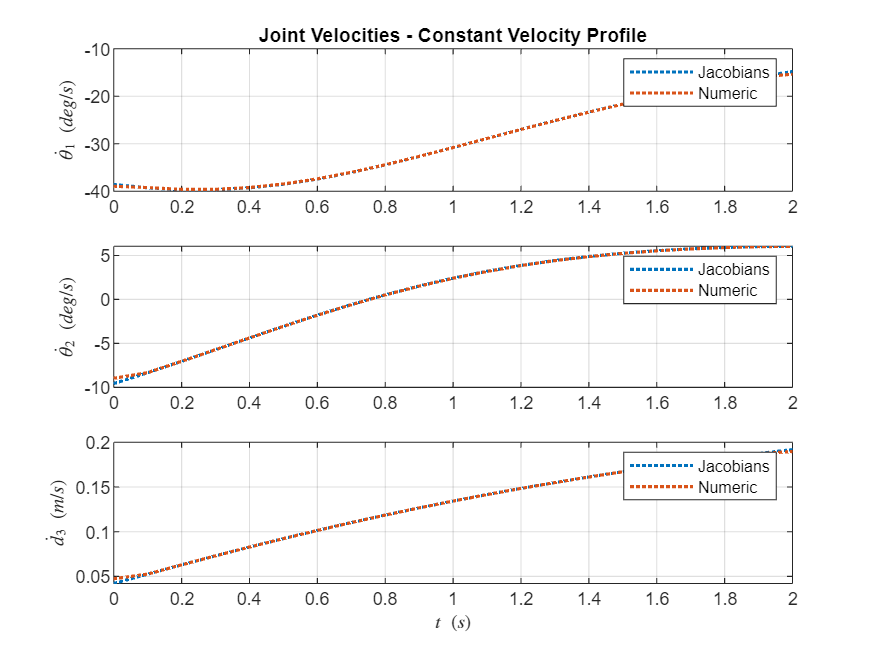

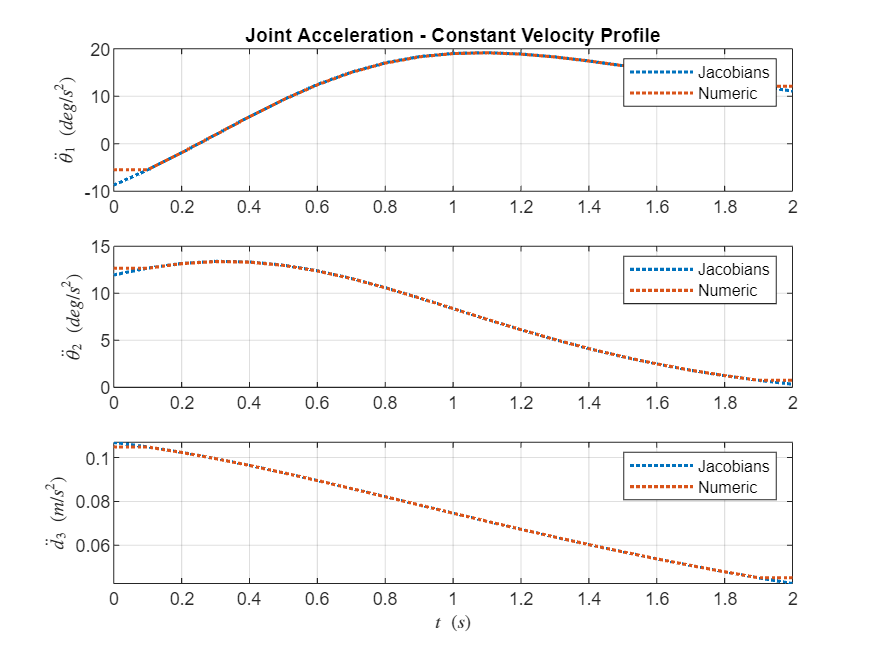

% Compute joint space position, velocity and accelerations
elbows = ones(length(t),2);
Q = q_plan("Constant", t, elbows);
Q_dot_jaco = q_dot_plan("Constant", t, elbows);
Q_ddot_jaco = q_dot2_plan("Constant", t, elbows);
% Numerical Differentiation of Qs
[Qdot_numeric, Qddot_numeric] = numerical_derivatives(Q, t);
Joint_traj_plotter("Constant", Q, Qdot_numeric, Q_dot_jaco, Qddot_numeric, Q_ddot_jaco, t) % to run in cmd

## Trapezoidal Velocity Profile

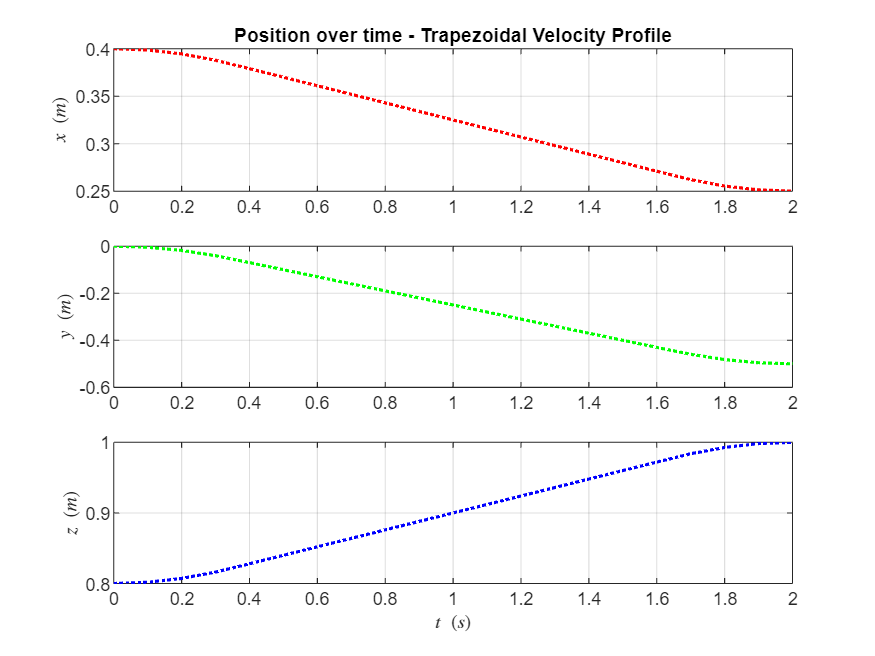

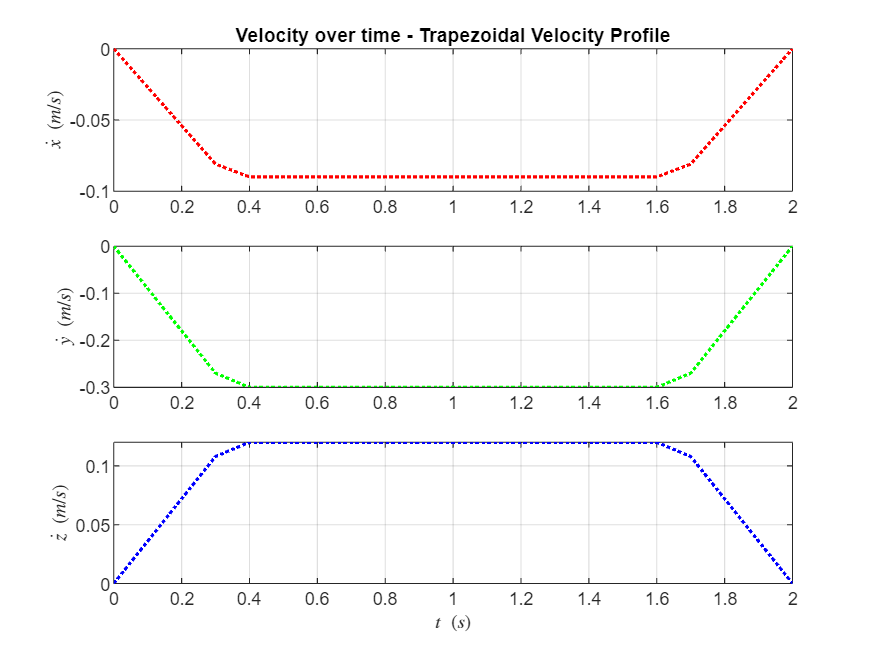

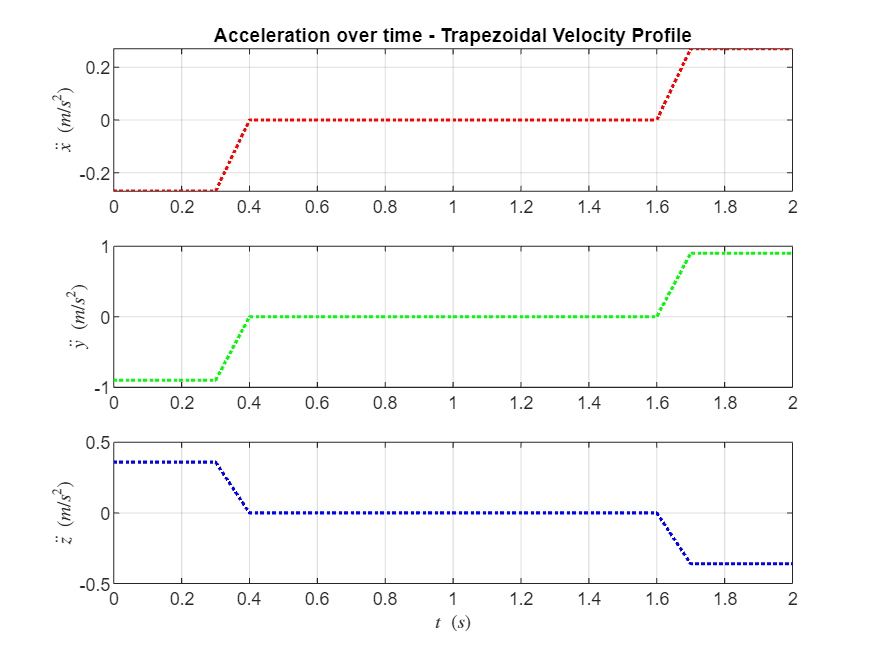

% Compute positions velocities and accelerations.
X = x_plan("Trapezoid", t); 
V = v_plan("Trapezoid", t); 
A = a_plan("Trapezoid", t);
Task_traj_plotter("Trapezoidal", X, V, A, t) % some custom function to plot everything neatly in Task Space

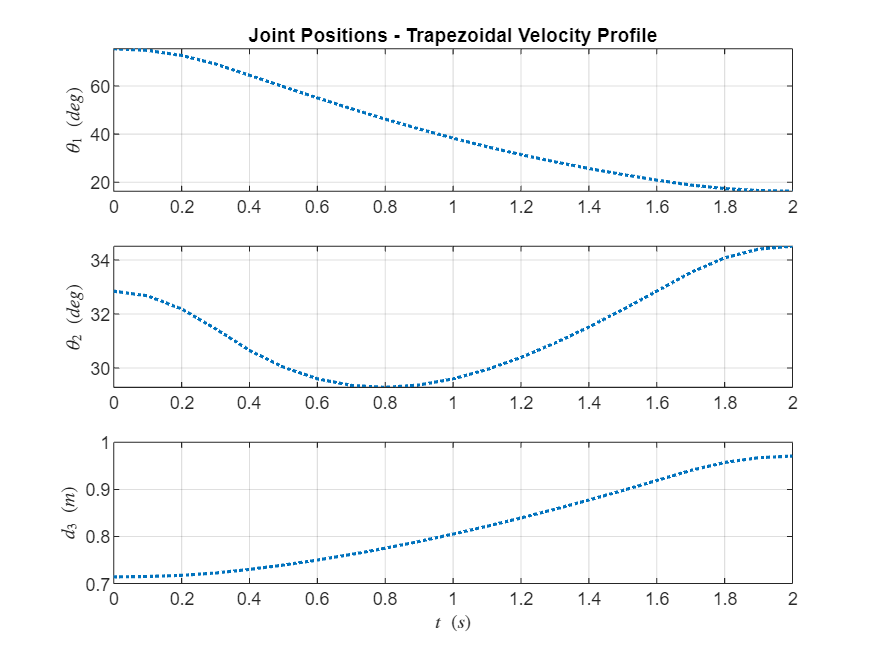

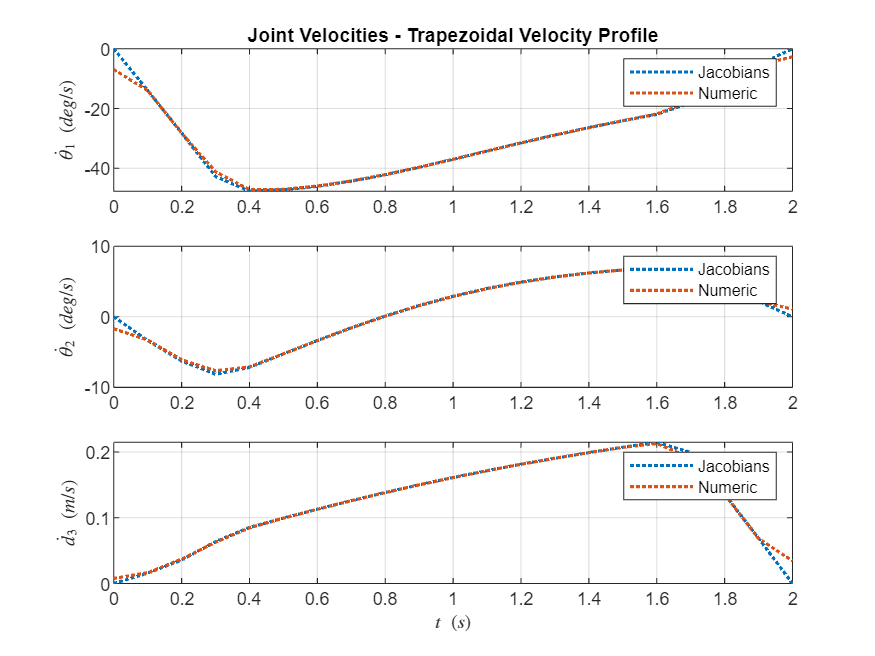

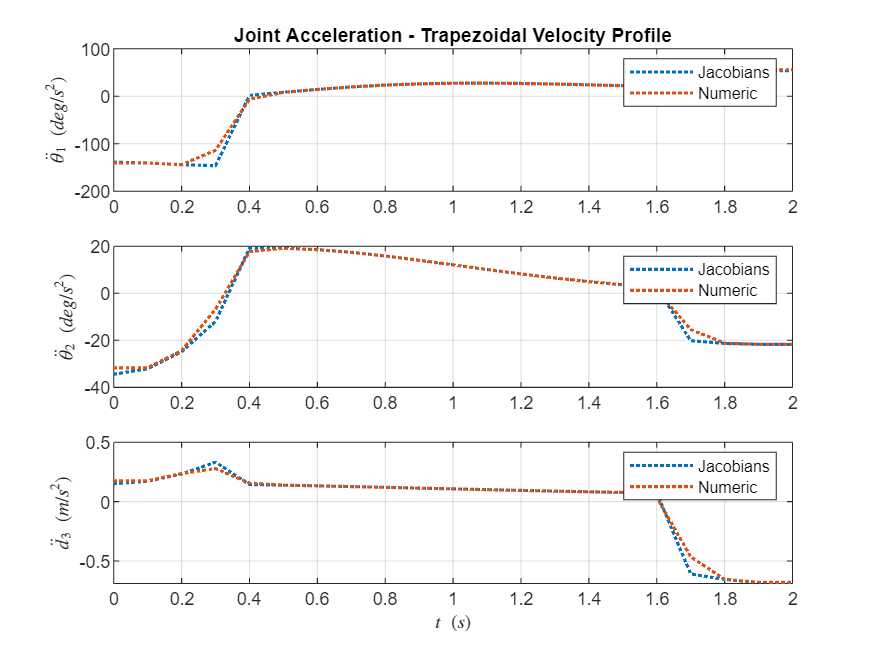

% Compute joint space position, velocity and accelerations
elbows = ones(length(t),2);
Q = q_plan("Trapezoid", t, elbows);
Q_dot_jaco = q_dot_plan("Trapezoid", t, elbows);
Q_ddot_jaco = q_dot2_plan("Trapezoid", t, elbows);
% Numerical Differentiation of Qs
[Qdot_numeric, Qddot_numeric] = numerical_derivatives(Q, t);
Joint_traj_plotter("Trapezoidal", Q, Qdot_numeric, Q_dot_jaco, Qddot_numeric, Q_ddot_jaco, t) % to run in cmd

## Polynomial Velocity Profile

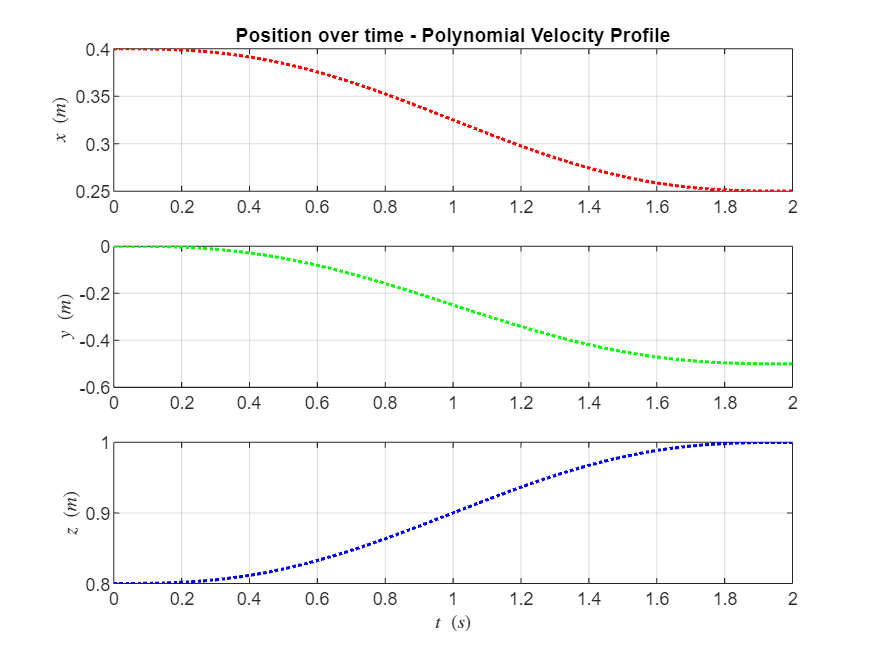

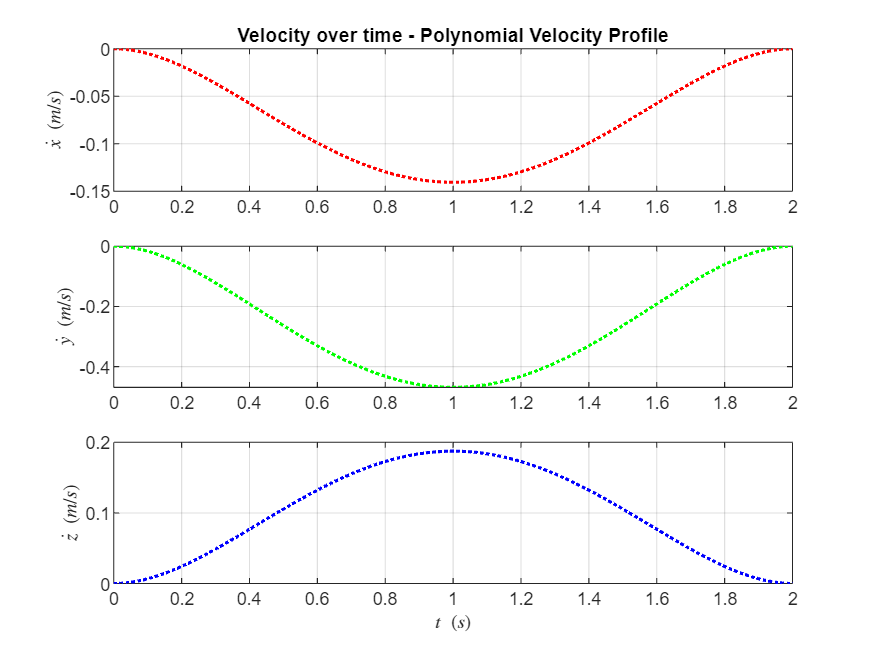

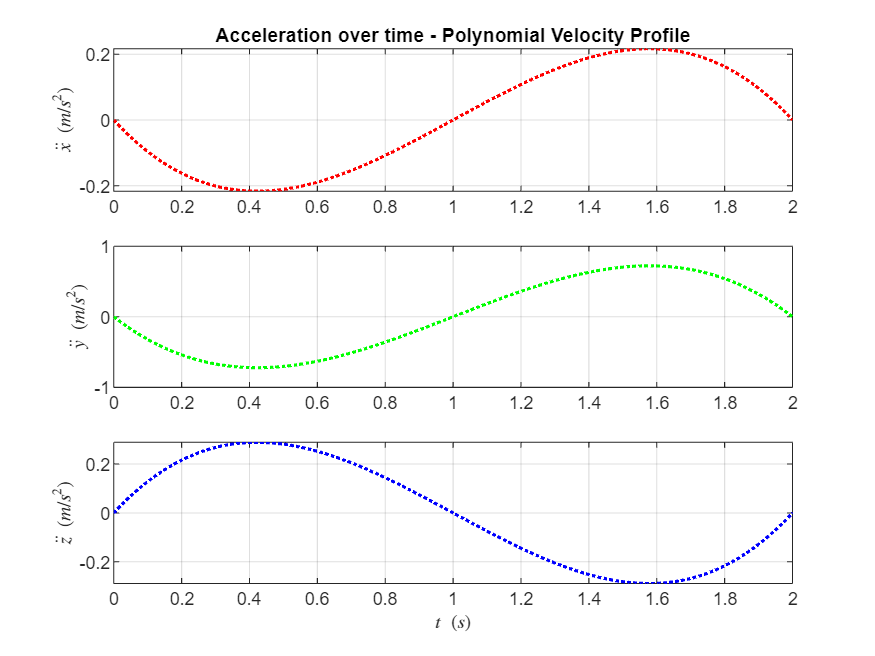

% Compute positions velocities and accelerations.
X = x_plan("Polynom", t); 
V = v_plan("Polynom", t); 
A = a_plan("Polynom", t);
Task_traj_plotter("Polynomial", X, V, A, t) % some custom function to plot everything neatly in Task Space

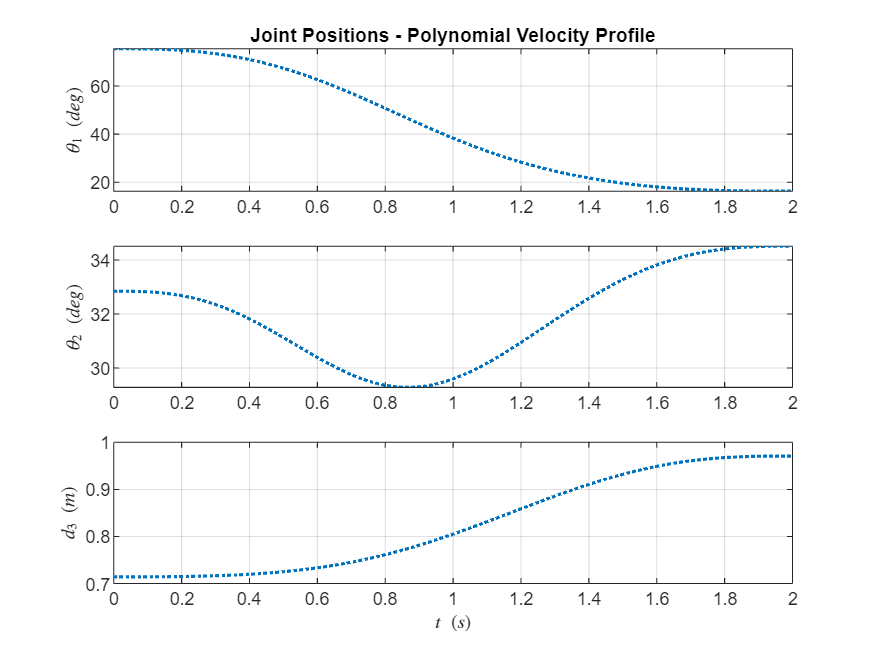

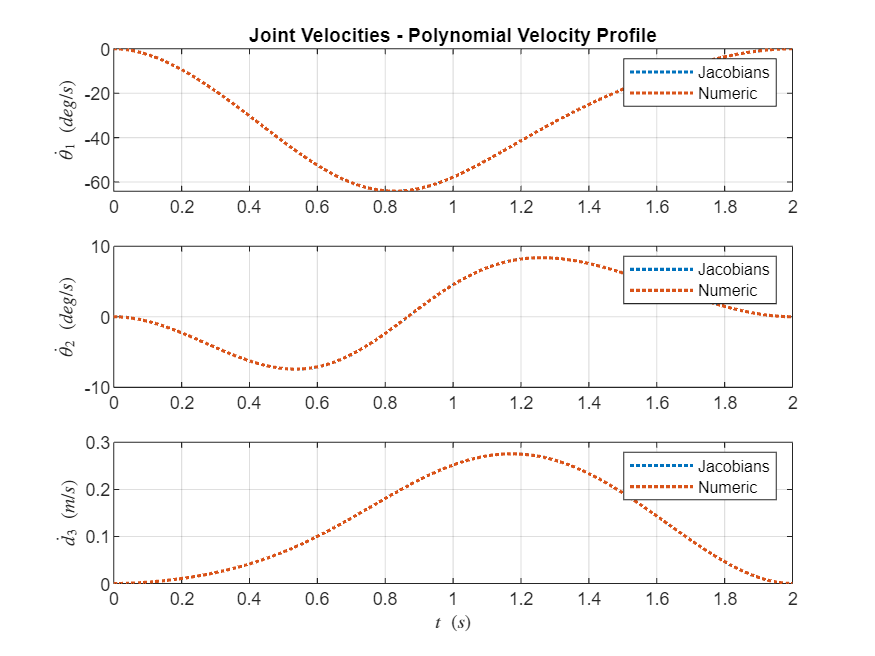

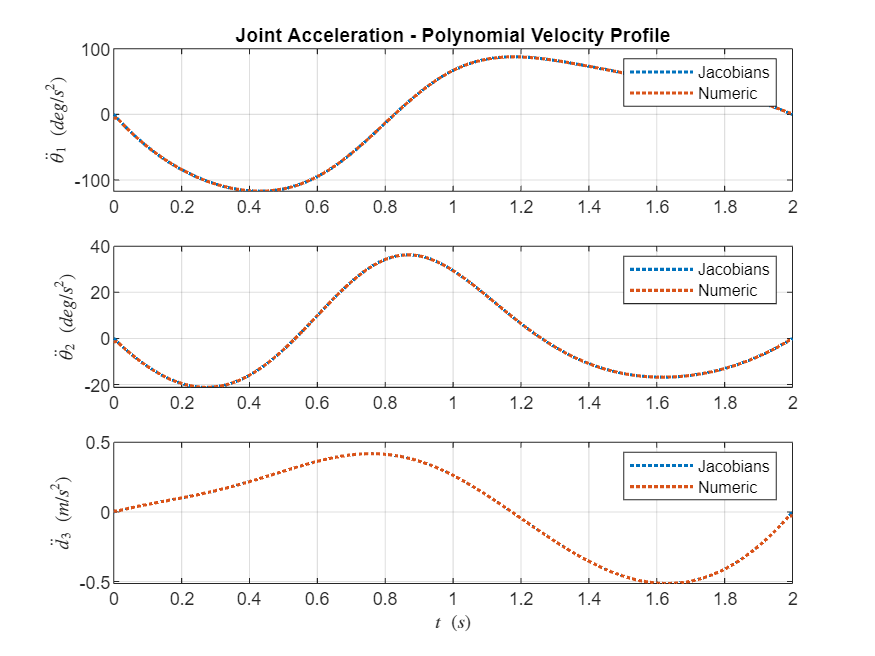

% Compute joint space position, velocity and accelerations
elbows = ones(length(t),2);
Q = q_plan("Polynom", t, elbows);
Q_dot_jaco = q_dot_plan("Polynom", t, elbows);
Q_ddot_jaco = q_dot2_plan("Polynom", t, elbows);
% Numeric Differentiation of Q
[Qdot_numeric, Qddot_numeric] = numerical_derivatives(Q, t);
Joint_traj_plotter("Polynomial", Q, Qdot_numeric, Q_dot_jaco, Qddot_numeric, Q_ddot_jaco, t) % to run in cmd